# Load data

load('Assignment_Data_SC42145.mat');
G = tf(FWT(1,1:2));

## Weight design

w_c1 = 1e-3;
w_c2 = 1e-1;
tau_pen = tf([w_c1],[1,w_c1]);
beta_pen = tf([1,0],[1,w_c2]);

Wu = [beta_pen 0; 0 tau_pen];
% Wp = tf([1/1.5, 0.25], [1, 0.25*1e-3]);
Wp = tf([1/1.1, 1*pi], [1, 1*pi*1e-4]);

plot weights

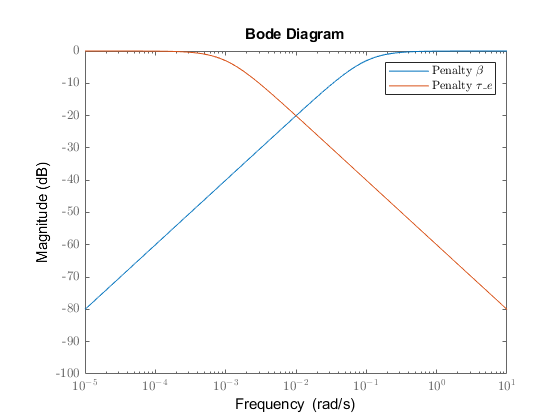

clf;
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
figure();
bodemag(beta_pen);
hold on
bodemag(tau_pen);
% latex_bodemag(tau_pen, "$W_u$")
legend("Penalty $\beta$", "Penalty ${\tau}_{e}$")

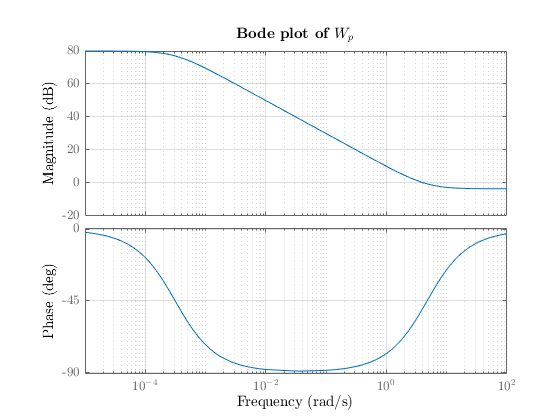

% saveas(gcf, 'Figures/ch3_mimo_weights_u_filter.eps',  'epsc')

figure()
latex_bode(Wp, "$W_p$")

% saveas(gcf, 'Figures/ch3_mimo_weights_p_filter.eps',  'epsc')


## H-infinity Controller Synthesis

P11=[Wp; zeros(size(Wu,2),size(Wp,1))]; P12=[Wp*(G); Wu]; P21=eye(size(Wp)); P22=G;
P = [P11 P12; P21 P22];

% H-infinity norm synthesis
[K, CL, gamma,syn_info] = hinfsyn(P, 1, 2); %2 inputs, 1 output
H_inf_norm_CL = gamma;

%define in/outputnames of K
K.InputName = {'dOmega'};
K.OutputName = {'Beta (deg)'; 'tau_e (Nm)'};
dOmega_sum = sumblk('dOmega = r - Omega (rad/s)');


%build closed loop transfer function
%first connect sum block with K by connecting inputs and outputs
%the new model has inputs [r,Omega,z] and outputs [beta, tau]
ref_tf = connect(dOmega_sum, -K,  {'r';'Omega (rad/s)'},{'Beta (deg)';'tau_e (Nm)'});
%these outputs are connected as inputs of the plant
%the inputs of the connected system are the exogenous inputs [r,V]
%we would like to monitor [r,z,Omega,tau,V], so these are the chosen outputs
outputs_ = {'r';'V (m/s)';'Omega (rad/s)'; 'Beta (deg)';'tau_e (Nm)'};
closed_loop = connect(ref_tf, FWT, {'r';'V (m/s)'}, outputs_);

closed_loop = minreal(closed_loop);

10 states removed.


## plotting of synthesis results (q3.4)

H_inf_norm_CL

H_inf_norm_CL = 1.4934

tf2latex(K)

d$\omega$ \to $\beta$ (deg)&=\frac{0.2296\,s^{19}+675.9\,s^{18}+4132.0\,s^{17}+27260.0\,s^{16}+1.34e+5\,s^{15}+3.899e+5\,s^{14}+1.462e+6\,s^{13}+2.294e+6\,s^{12}+5.538e+6\,s^{11}+4.51e+6\,s^{10}+1.889e+6\,s^9+6.415e+5\,s^8+1.724e+5\,s^7+33090.0\,s^6+6087.0\,s^5+693.8\,s^4+74.65\,s^3+4.565\,s^2+0.002846\,s+4.459e-7}{s^{20}+2946.0\,s^{19}+4164.0\,s^{18}+98460.0\,s^{17}+1.2e+5\,s^{16}+1.106e+6\,s^{15}+1.14e+6\,s^{14}+4.297e+6\,s^{13}+3.593e+6\,s^{12}+1.42e+6\,s^{11}+4.83e+5\,s^{10}+1.267e+5\,s^9+22640.0\,s^8+4406.0\,s^7+400.0\,s^6+54.59\,s^5+1.614\,s^4+0.04247\,s^3+3.909e-5\,s^2+1.218e-8\,s+1.27e-12}
d$\omega$ \to $\tau_e$ (Nm)&=\frac{1.484e+6\,s^{19}+2.915e+6\,s^{18}+5.088e+7\,s^{17}+8.83e+7\,s^{16}+5.942e+8\,s^{15}+8.907e+8\,s^{14}+2.519e+9\,s^{13}+3.059e+9\,s^{12}+1.837e+9\,s^{11}+7.297e+8\,s^{10}+2.327e+8\,s^9+5.78e+7\,s^8+1.127e+7\,s^7+1.882e+6\,s^6+2.228e+5\,s^5+21800.0\,s^4+1335.0\,s^3+2.133\,s^2+0.0009475\,s+1.283e-7}{s^{20}+2946.0\,s^{19}+4164.0\,s^{18}+98460.0\,s^{17}+1.2e+5\,s^

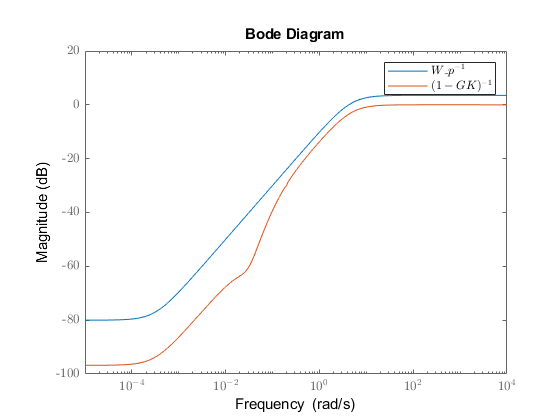


figure(); bodemag(inv(Wp)); hold on;
S = 1/(1-G*K); bodemag(S)% latex_bodemag(S," weights vs controller");
legend("${W_p}^{-1}$", "$(1-GK)^{-1}$")

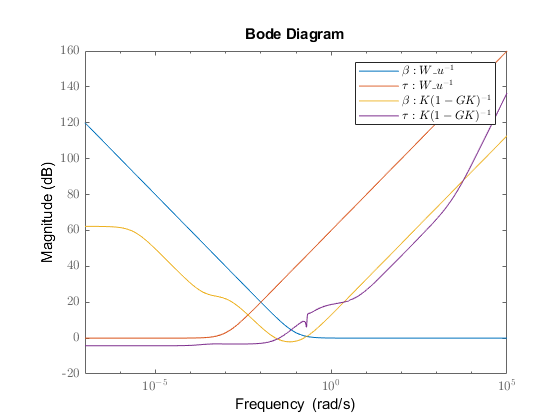

% saveas(gcf, 'Figures/ch3_weights_vs_controller_p.eps',  'epsc')

figure(); bodemag(inv(Wu(1,1))); hold on;
bodemag(inv(Wu(2,2)));
bodemag(Wu(1,1)*K(1,:)\(1-G*K)); 
bodemag(Wu(2,2)*K(2,:)\(1-G*K));
% latex_bodemag(Wu(2,2)*K(2,:)\(1-G*K(:,1))," weights vs controller");

legend("$\beta: W_{u}^{-1}$", "$\tau: W_{u}^{-1}$", "$\beta: K(1-GK)^{-1}$", "$\tau: K(1-GK)^{-1}$");

% saveas(gcf, 'Figures/ch3_weights_vs_controller_u.eps',  'epsc')

## Performance assessment

using step response

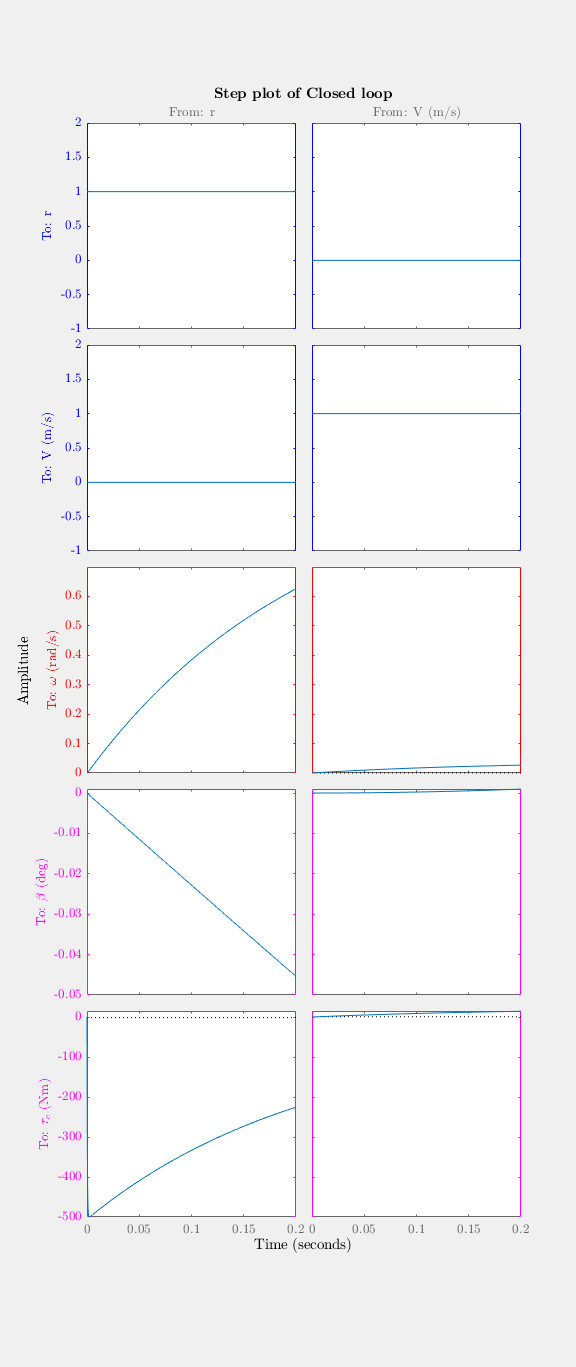

clf

figsize = [0,0,6,4 *6];

figure('units','inch','position',figsize);

latex_step(closed_loop, "Closed loop")
%[Y_sim, T_sim] = step(closed_loop);
axs= findobj(allchild(gcf), 'flat', 'Type', 'axes');

%exogenous inputs
axs(end).YColor='Blue';
axs(end-1).YColor='Blue';
axs(6).YColor='Blue';
axs(5).YColor='Blue';

%outputs
axs(end-2).YColor='Red';
axs(4).YColor='Red';

%control inputs
axs(8).YColor='Magenta';
axs(7).YColor='Magenta';
axs(3).YColor='Magenta';
axs(2).YColor='Magenta';

set(gcf,'Visible','on')



% saveas(gcf, 'Figures/ch2_mimo_simulation.eps',  'epsc')


## Time Domain Simulation using wind data

Plot wind data

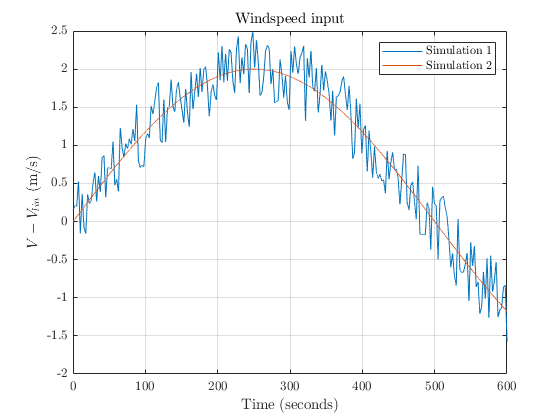

figure()
plot(Wind_Data)
hold on
t_d = Wind_Data.Time;
plot(t_d, sin(t_d*(2e-3*pi))*2);
grid on
legend("Simulation 1", "Simulation 2")
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
xlabel("Time (seconds)", 'interpreter', 'latex')
ylabel("$V-V_{lin}$ (m/s)", 'interpreter', 'latex')
title("Windspeed input", 'interpreter', 'latex')


% saveas(gcf, 'Figures/ch3_wind_input.eps',  'epsc')

Perform simulation

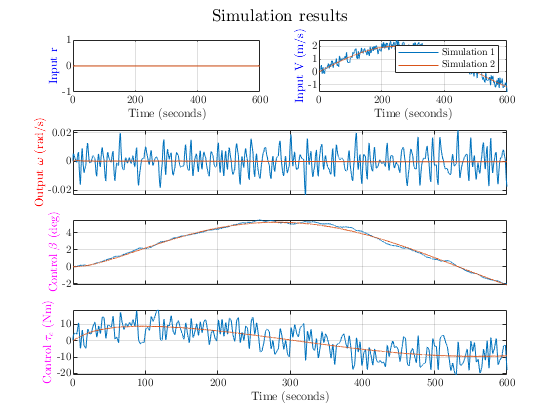

%to resample the input to evenly spaced timesteps:
figure(1)

dt = mean(diff(t_d));
t = min(t_d):dt:max(t_d);
u_1 = resample(Wind_Data,t).Data';
u_2 = sin(t*(2e-3*pi))*2;
latex_lsim(closed_loop(:,2), u_1,t, [2,1,2],u_2);

% saveas(gcf, 'Figures/ch3_sim_output.eps',  'epsc')